# ME 140 Final Exam Practice

## E2 P21

f = @(x)-8 -12*x+8*x.^2-3.25*x.^3; % cont
xl = -1; xu = 0; es = 0.01;
help bisect

 bisect: root location zeros
  [root,relErr,iter] = bisect(func,xl,xu,es,maxit,p1,p2,...)
  input:
    func = function handle (@)
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%) (input %)
    maxit = maximum allowable iterations (default 50)
    p1,p2... = additional parameters used by func
  output:
    root = real root
    relErr = approximate relative error (%)
    iter = number of iterations



[root,relErr,iter] = bisect(f,xl,xu,es)

root = -0.4817

relErr = 0.0063

iter = 15


help falsepos

  falsepos: root location zeroes
  [root,froot,ea,iter]=falsepos(func,xl,xu,es,maxit,p1,p2,...):
  uses false position to find the root of func
  input:
    func = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = root estimate
    froot = function at root estimate
    ea = approximate relative error (%)
    iter = number of iterations



[root,froot,ea,iter]=falsepos(f,xl,xu,es)

root = -0.4817

froot = -2.1248e-04

ea = 0.0059

iter = 8

## E2 P22

help modSecant

 xr=modSecant(f,x0,delta,tol,maxIt)
 
 Implements the modified secant method
 
  f = function to find the root of
  x0 = initial value
  delta = value of delta
  tol = stopping criteria tolerance
  maxIt = maximum number of iterations
  xr = found root
 
 ABH
 Spring 2023



delta = 0.001; x0 = 3.5;
xr=modSecant(f,x0,delta, 0.1)

xr = -0.4817


coeff

## E2 P23

help goldmin

  goldmin: minimization golden section search
  [x,fx,ea,iter]=goldmin(f,xl,xu,es,maxit,p1,p2,...):
  uses golden section search to find the minimum of f
  input:
    f = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by f
  output:
    x = location of minimum
    fx = minimum function value
    ea = approximate relative error (%)
    iter = number of iterations
  Can find max w/ g(x) = -f(x) -> max of f(x) = -g(x)



f = @(x) 2*x.^4+x.^3+10*x.^2+4*x;
xl = -2; xu = 1;
[x,fx,ea,iter]=goldmin(f,xl,xu,0.1)

x = -0.2028

fx = -0.4049

ea = 0.0978

iter = 19

g =@(x) -1*f(x);
[xmax,fxmax,eamax,itermax]=goldmin(g,xl,xu,es)

xmax = -1.9998

fxmax = -55.9825

eamax = 0.0099

itermax = 19

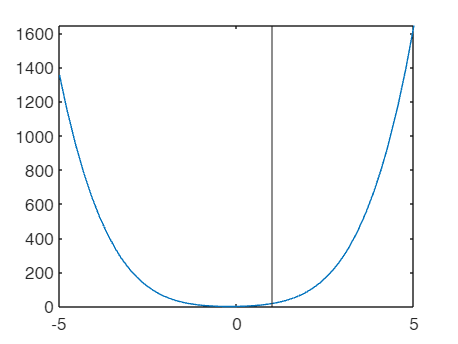


fplot(f); hold on
xline(1); hold off


help fminbnd

 fminbnd Single-variable bounded nonlinear function minimization.
    X = fminbnd(FUN,x1,x2) attempts to find  a local minimizer X of the function 
    FUN in the interval x1 < X < x2.  FUN is a function handle.  FUN accepts 
    scalar input X and returns a scalar function value F evaluated at X.
 
    X = fminbnd(FUN,x1,x2,OPTIONS) minimizes with the default optimization
    parameters replaced by values in the structure OPTIONS, created with
    the OPTIMSET function. See OPTIMSET for details. fminbnd uses these
    options: Display, TolX, MaxFunEval, MaxIter, FunValCheck, PlotFcns, 
    and OutputFcn.
 
    X = fminbnd(PROBLEM) finds the minimum for PROBLEM. PROBLEM is a
    structure with the function FUN in PROBLEM.objective, the interval
    in PROBLEM.x1 and PROBLEM.x2, the options structure in PROBLEM.options,
    and solver name 'fminbnd' in PROBLEM.solver. 
 
    [X,FVAL] = fminbnd</

X = fminbnd(f,xl,xu)

X = -0.2028

## E2 P24